# 2. Mechanical Model

## 2.1 Overview

In this part we are going to assemble the mechanical model of the balancing robot using Simscape Multibody. Simscape Multibody lets you define the individual parts (bodies) by using parametric blocks or importing CAD files. These parts can be connected to form larger assemblies using connections. Other relations for describing degrees of freedom (DOF) between the bodies can be modeled with additional blocks such as joints.

The characteristics of the body parts, such as the weight can be defined in the corresponding block options. To keep the model as accurate as possible, we should adapt these physical properties to the real values e.g. by weighing the components. Similar to the chapter before, this can be done using the block parameters.

## 2.2 General considerations

When building the model for the balancing robot we have to make sure that the signals have the same signs and units as in reality. To facilitate this we stick to the conventions depicted in the figure below. Angular positions and speeds are in rad and rad/s. The signs of the signals is such that the arrows point in positive direction. These conventions are given by the hardware specifications ([see user manual](matlab:open('..\Specs\balboa_32u4_robot.pdf'))). 

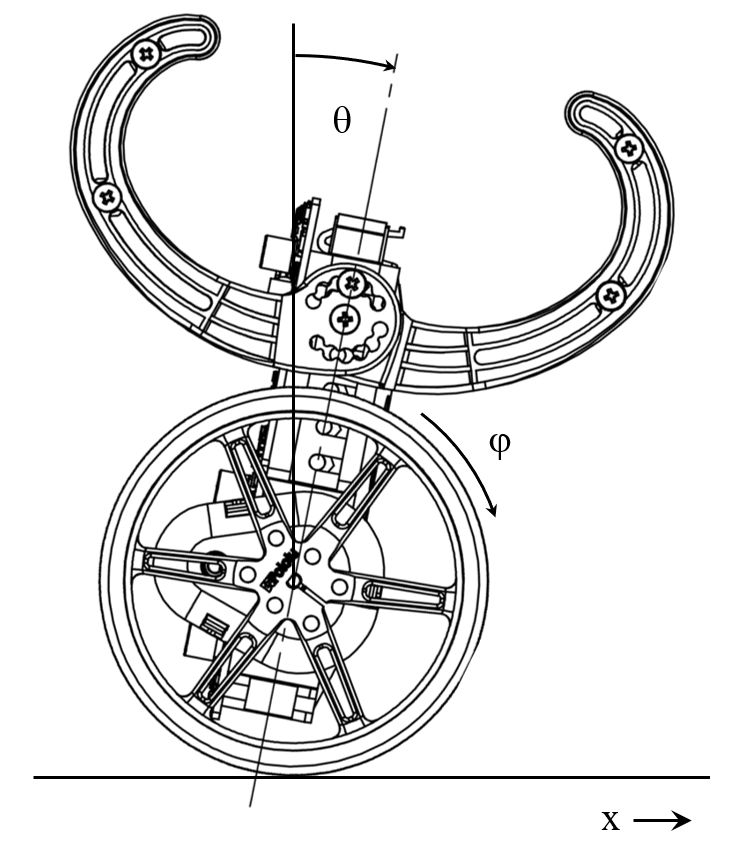

## 2.3 Draft Mechanical Model in Simscape Multibody

Let's now create a mechanical model from scratch step by step. For this we can use the multibody template. At this stage it is important to include all the relevant interactions such as contact with the floor as well as all the DOF. 

### Solid bodies

- First we model the robot as a simple block solid. This is already given in the template. We only have to adjust its dimensions. Let's chose them as [2 8 10] cm.

- The initial orientation of the body can be defined using the Rigid Transformation Block. This is already present as well. Please add a translation offset in z direction of 9 cm. This is required in order to position the center of mass above the floor.

- To allow for free movement of the robot we have to add a joint that grants DOF. For the demonstration of the concept let's use a 6 DOF joint. (Note: In fact we do not need all these DOF and we will model this differently in subsequent sections.)

- Add a plane on which the robot will move at a later stage.

- Note: based on these principles one can create larger assemblies of parts. One can also add CAD files to reduce modeling effort.

After these steps the model should look as follows:

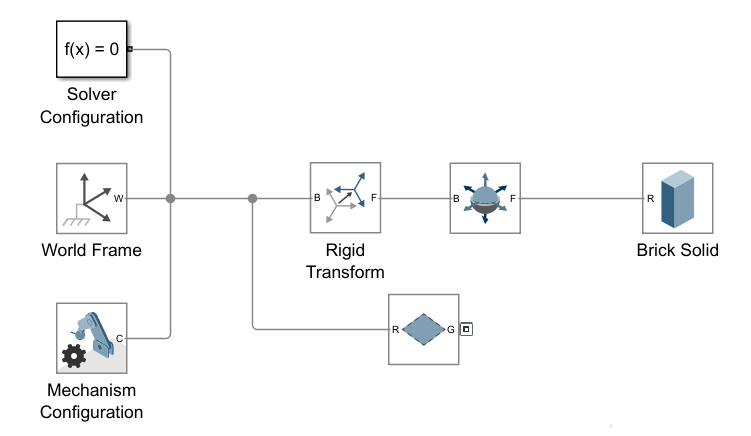

### Connection of Objects - Adding Wheels

To connect the main body to the wheels and to model interactions with the floor we have to define additional frames for the main body. These frames are reference points with associated coordinate systems that define how bodies are positioned and move with respect to each other.

- To define the attach points for the wheels we add two additional frames. They can be added in the block parameters by clicking on the "+" button under "Frames".

- In the "Create Frame" dialogue, we select "Frame Origin" as "Based on Geometric Feature". After clicking a feature in the 3D view (this can be a vertex, edge or face), you see where the new frame will be positioned including its orientation. After clicking on "Use Selected Feature" you can further modify the frame orientation using the "Frame Axes" options. Make sure that the primary +Z axis is aligned with the +Y axis of the reference frame. Once satisfied, you can click on save.

- Note: please feel free to give those frames meaningful names.

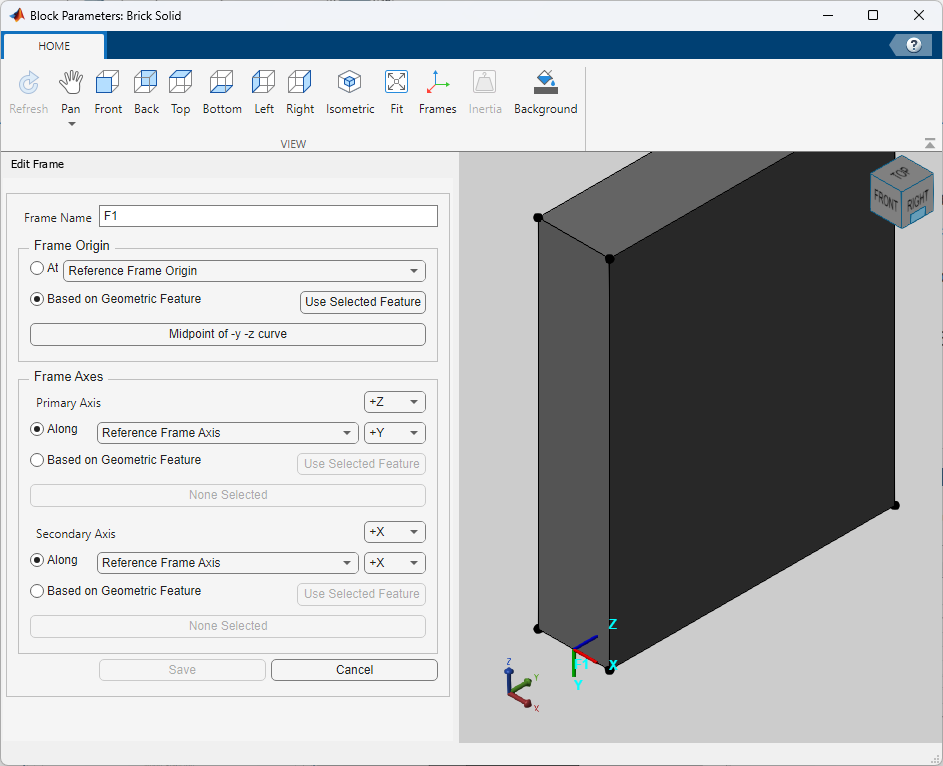    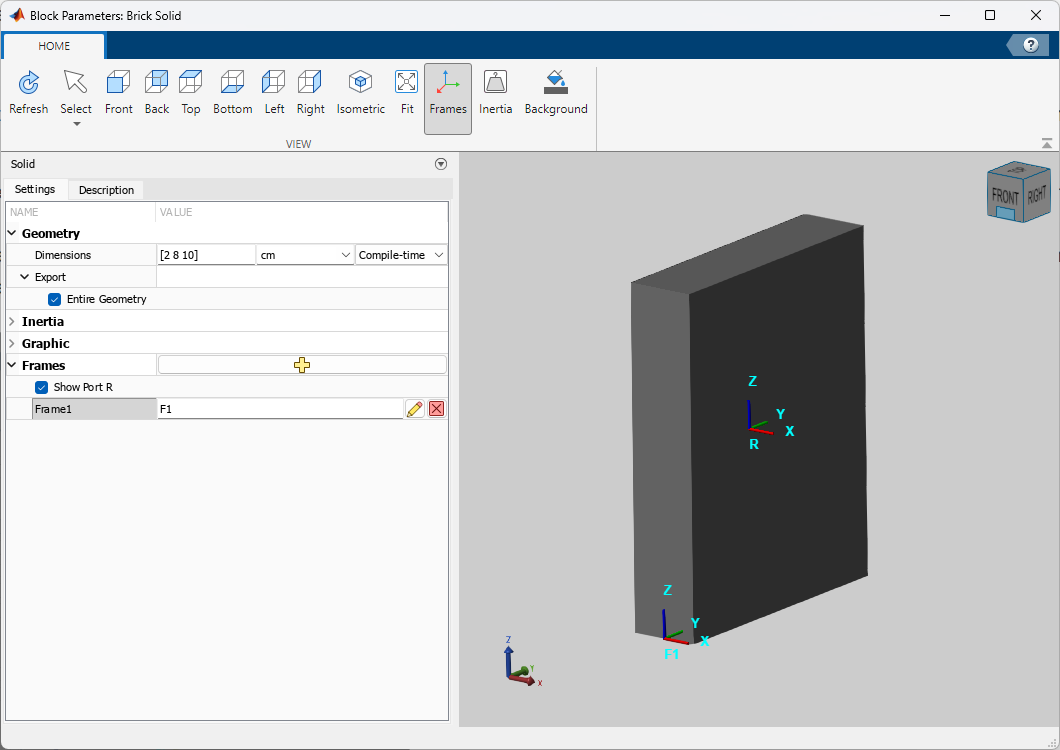

- To these frames we attach revolute joints. The rotation is always around the z axis of the base frame.

- Then we model the wheels using the cylindrical solid and connect them to the just created frames. Again, set the physical properties of the wheels according to the real world objects. Note that when connecting bodies their connected frames (coordinate systems) will be aligned accordingly.

The state of the model should be like this now:

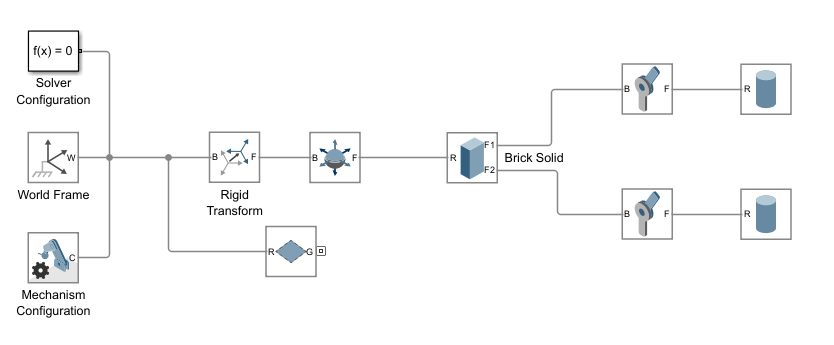

### Interactions with other Bodies

- To model interactions with other bodies such a rolling or sliding over a surface we have to create geometry ports for the main body and the wheels. This can be set in the block parameters under Geometry -> export (complete geometry or convex hull)

- The resulting ports are then connected to the "spatial contact force" blocks.

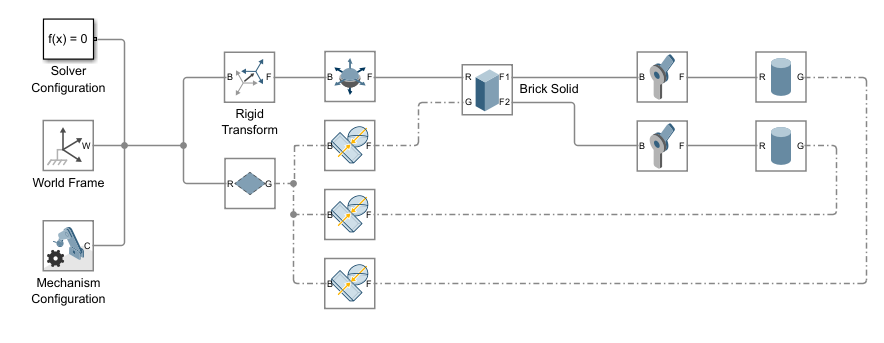    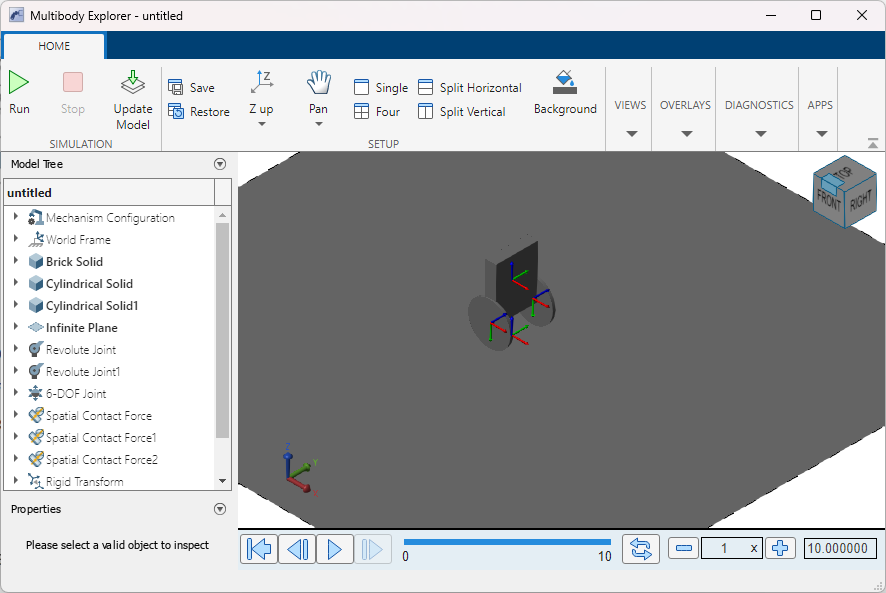

open_system("Ex4_1_Dummy_Model")

### Measurement of Body Properties

To measure properties of the parts such as position or velocities we can enable additional outputs of the joint blocks or use the Transform Sensor block. For the latter, the properties of a body, which is typically called the follower (F), are always measured with respect to a reference frame, called the base (B), e.g. the world frame.

Exercise: Try to measure the angle and position of the robot body.

### Side note: Actuation of Joints

In order to turn the wheels, one can enable the actuation of the joints using an input signal. This is left as an exercise for the interested reader. For our model we will not use this approach because we want to replace the revolute joints with the motor blocks designed in the previous chapter.

## 2.4 Refining the Mechanical Model and Adding Motors

The next step in the model evolution is quite huge and we only outline the main actions here. It comprises a refactorization of the model that includes the following:

- Replacing dummy parts with CAD files

- implement measurements of the body transformations (speeds, position)

- Organize the blocks for the main body into a subsystem and create a library for the wheels (this step helps to separate the environment from the robot)

- Insert motor models from the library and connect the main body subsystem with the motors and wheels.

- Create a reusable library model for the entire robot (w/o the environment)

In this process we separate the world components such as the configurations and the floor from the mechanical model of the robot (see figure in section 2.5). Structuring the model in such a modular way makes it easier to modify and test it. The library block for the robot model now looks as follows: 

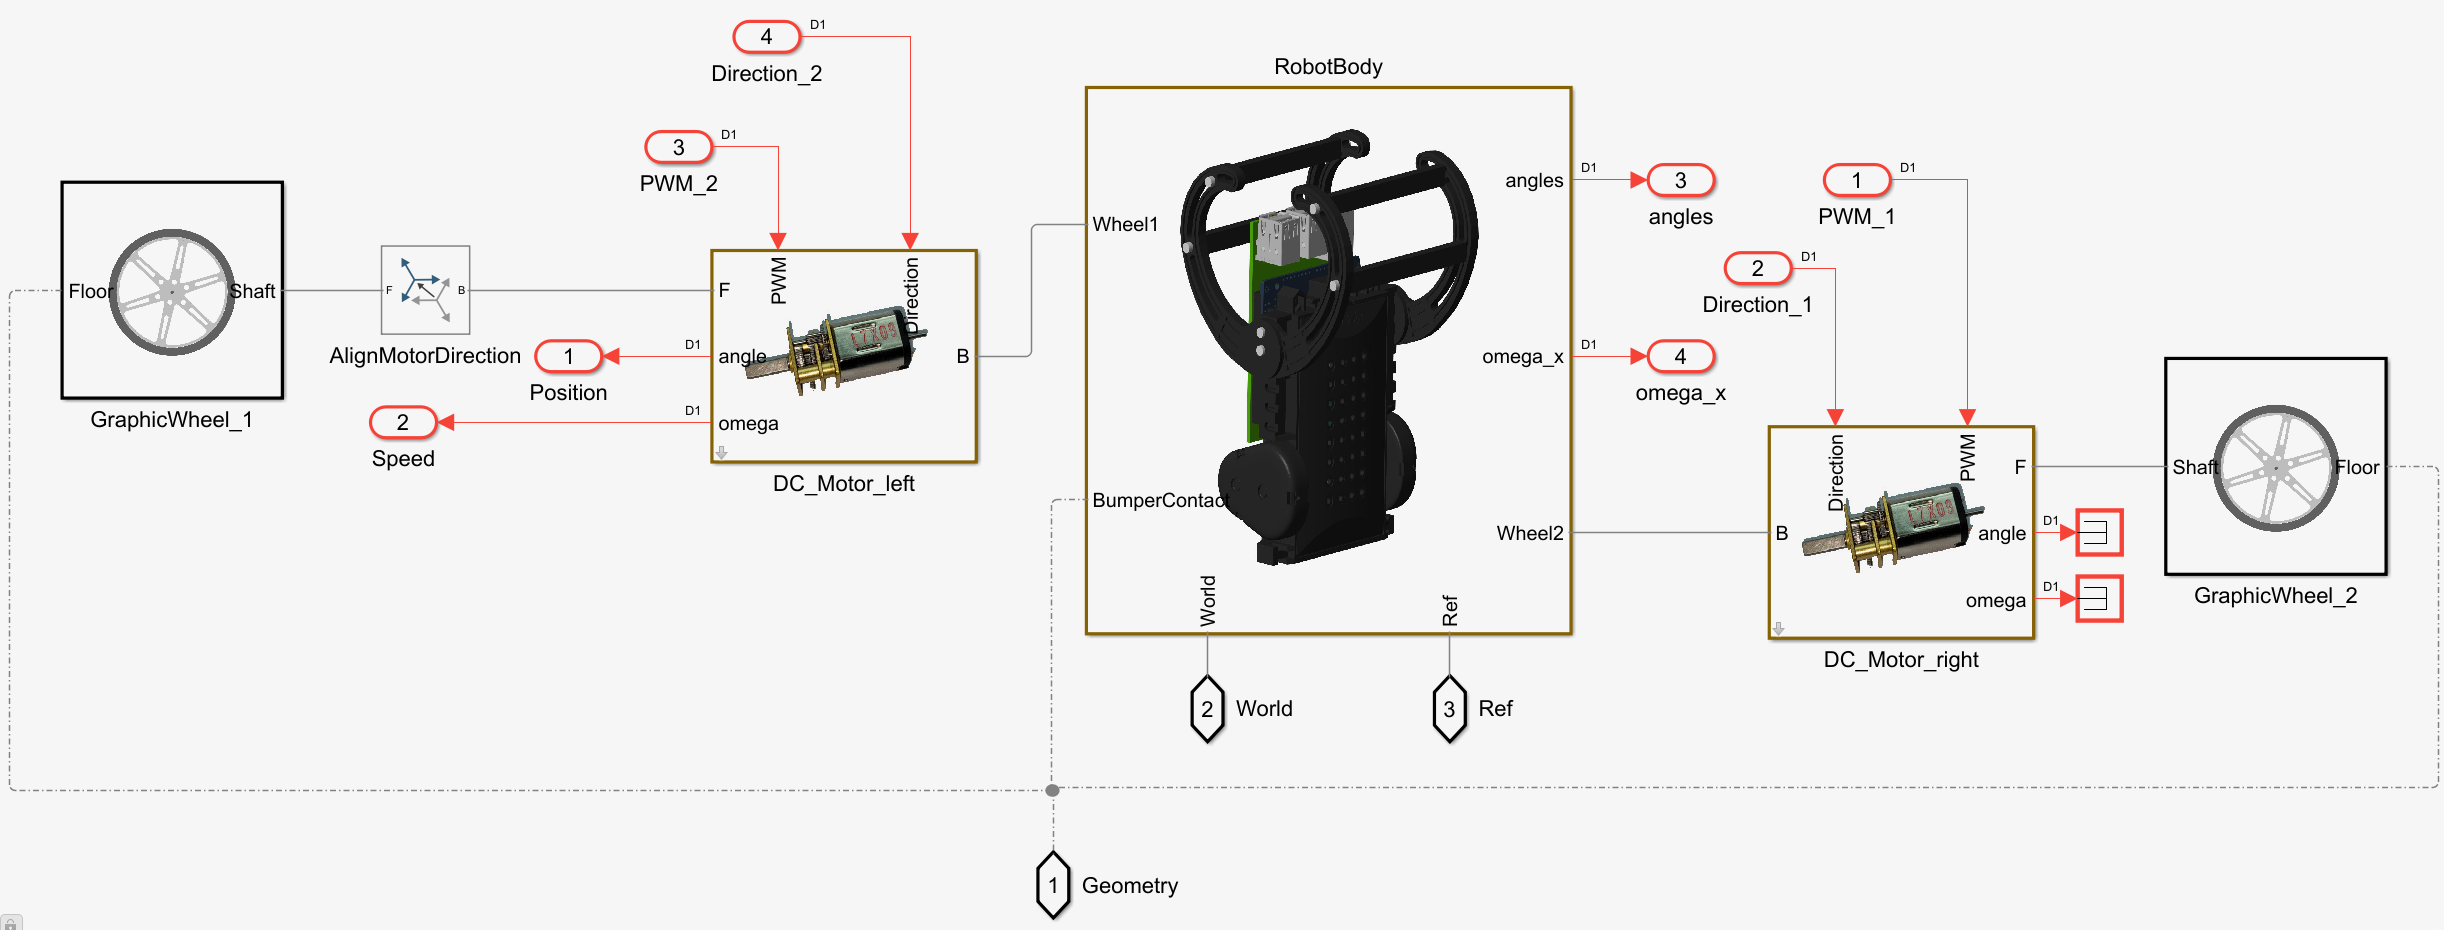

## 2.5 Adding the Speed Controller and Validation of the Model

We can now add the speed control algorithm that we used in the previous chapter and validate the behavior of the model. During this process it is of utmost importance to check that all the inputs and measurements are in agreement with reality.

Especially, please make sure that all the signs and magnitudes of the states behave as defined.

## 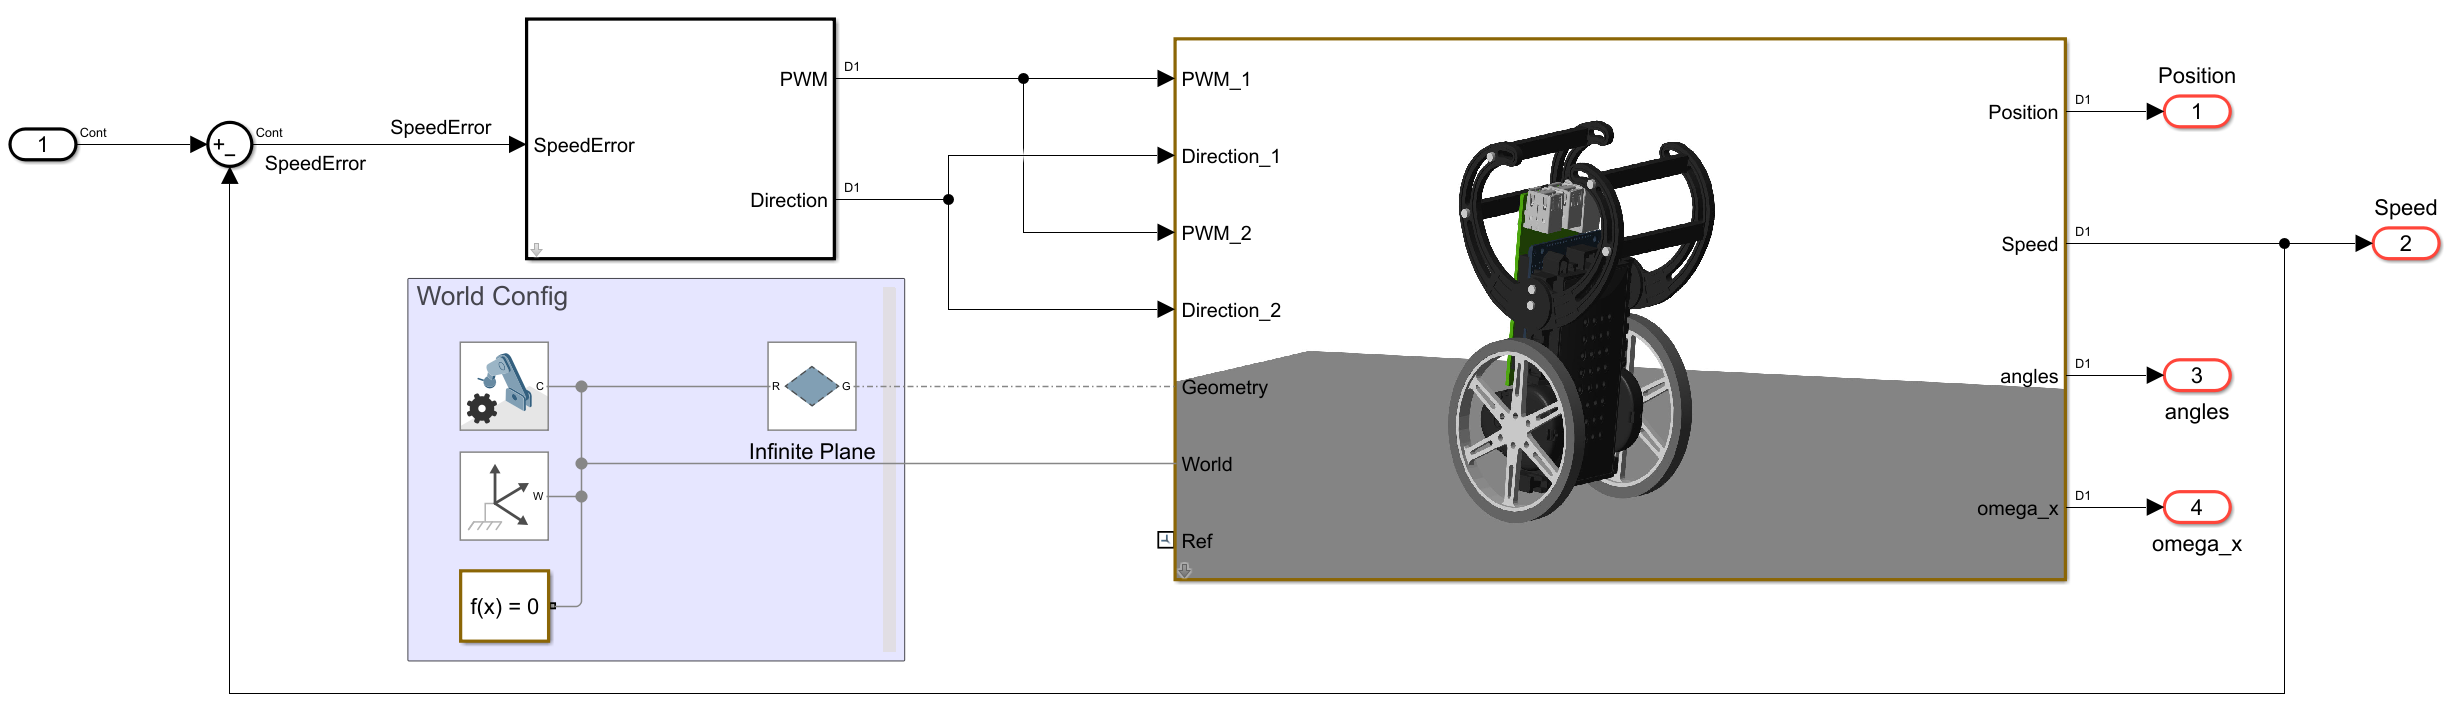

You can easily make a first validation by simulating the model with static speed setpoints and observing the state vectors

open_system("Ex4_Mechanical_Model_For_Simulation")